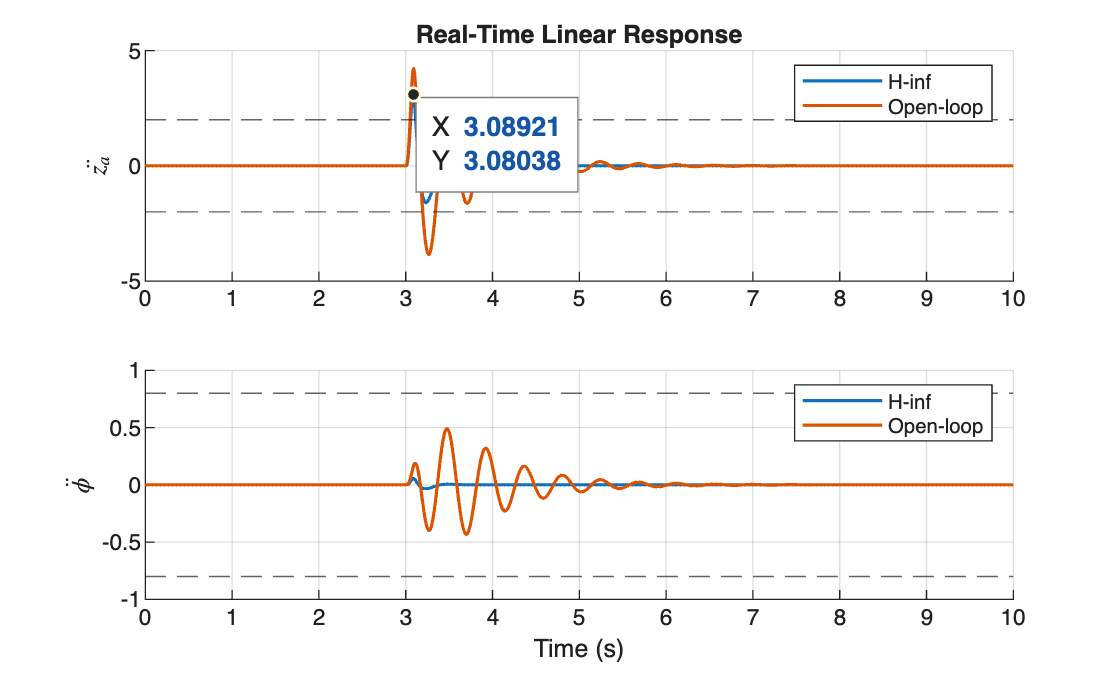

w1_val = 3; 
w2_val = 5; 

u1_val = 3;
u2_val = 8;

% Sim param
Ts = 1e-5;
t_sim = 0:Ts:10; 

function noise_profile = calc_noise(t, A, V, l)
    % Delay start by 3 seconds
    delay = 3;
    noise_profile = zeros(size(t));
    activeTime = t >= delay & t <= (l / V) + delay;
    shiftedTime = t(activeTime) - delay;
    noise_profile(activeTime) = (A / 2) * (1 - cos((2 * pi * V / l) * shiftedTime));
end

% 1. Re-build constraints based on slider values
Winf = W(w1_val, w2_val); 
Cinf = C(Winf); 
Dinf = D(Winf, u1_val, u2_val);
matrices_hinf = matrices(Cinf,Dinf);

% Lmi
contrHinf = Controllers(matrices_hinf, hinf, 1);
[Kinf, minval] = contrHinf.solve;

% cl sys
sys_cl_hinf = ss(A + B*Kinf, B2, C1 + D12*Kinf, zeros(2,2));

% disturbance
w = calc_noise(t_sim,noise.A,noise.V,noise.l)';
w = [w, w];

% Simulate closed-loop response to the generated input
[y_hinf, t_hinf, x_hinf] = lsim(sys_cl_hinf, w, t_sim);

u = Kinf * x_hinf';

% Plot
figure; hold on;

subplot(2,1,1); hold on; grid on;
title('Real-Time Linear Response');
plot(t_hinf, y_hinf(:,1), 'LineWidth', 1.2);
plot(t_hinf, y_free_noise(:,1), 'LineWidth', 1.2);
yline(az_max,'LineStyle','--'); yline(-az_max,'LineStyle','--');
ylabel('$\ddot{z_a}$','Interpreter','latex');
legend('H-inf','Open-loop');
hold off;

subplot(2,1,2); hold on; grid on;
plot(t_hinf, y_hinf(:,2), 'LineWidth', 1.2);
plot(t_hinf, y_free_noise(:,2), 'LineWidth', 1.2);
yline(aphi_max,'LineStyle','--'); yline(-aphi_max,'LineStyle','--');
legend('H-inf','Open-loop');
hold off;

xlabel('Time (s)');
ylabel('$\ddot{\phi}$','Interpreter','latex');
hold off;

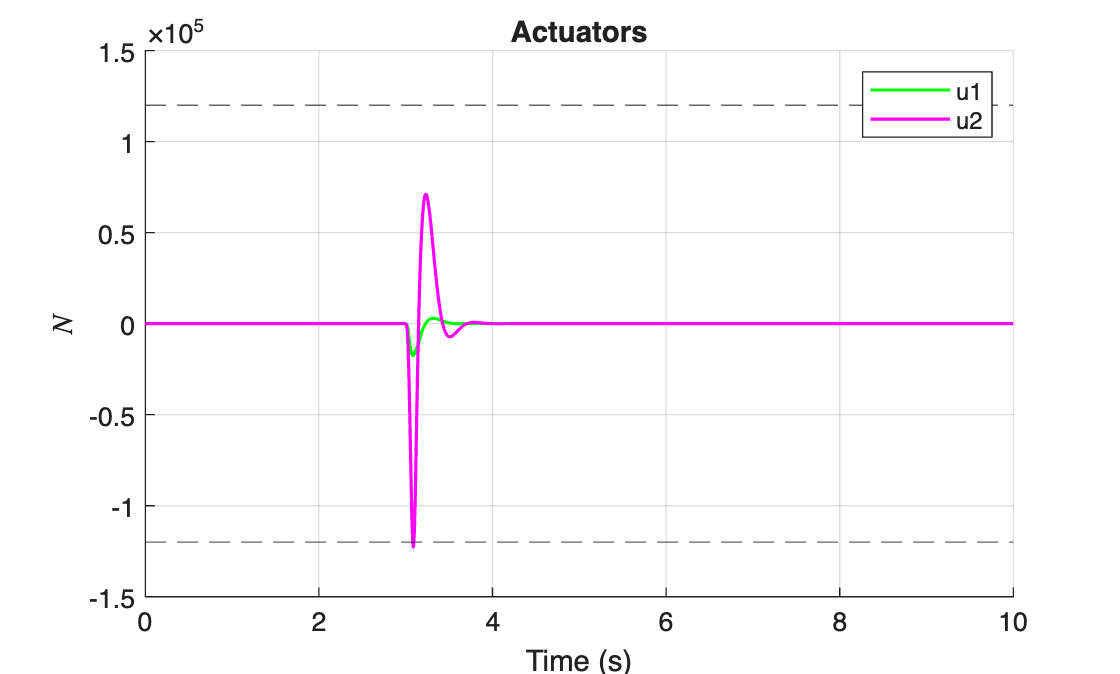


figure; hold on;
grid on;
title('Actuators');
plot(t_hinf, u(1,:), 'LineWidth', 1.2, 'Color', 'g');
plot(t_hinf, u(2,:), 'LineWidth', 1.2, 'Color', 'm');
yline(umax,'LineStyle','--'); yline(-umax,'LineStyle','--');
ylabel('$\ddot{z_a}$','Interpreter','latex');
legend('u1','u2');
xlabel('Time (s)');
ylabel('$N$','Interpreter','latex');
hold off;